# 1. Transfer Learning

## Overview of Pretrained Convolutional Neural Networks

Load AlexNet into a network variable in MATLAB

net = alexnet  % Error? Then, install 'Deep Learning Toolbox Model for AlexNet Network' in Add-Ons Explorer

net =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


Peek into AlexNet

% View the layers of AlexNet and save the layers to a variable
layers = net.Layers

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU             ReLU
     4   'norm1'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU             ReLU
     8   'norm2'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU             ReLU
    12   'conv4'    그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'    ReLU             ReLU
    14   'conv5'    


% Save the first and last layers of AlexNet
layer_input = layers(1)

layer_input =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [227 227 3]

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


layer_output = layers(end)

layer_output =   ClassificationOutputLayer - 속성 있음:

            Name: 'output'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   하이퍼파라미터
    LossFunction: 'crossentropyex'




% View the output classes of AlexNet
classes = layer_output.Classes

classes = 1000×1 categorical 배열
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


## Preprocessing an Image

Import an image and resize it to be compatible with AlexNet

% Display an image
image = imread("harper.jpg")

image = 400×305×3 uint8 배열
image(:,:,1) =

   110   110   110   112   113   115   116   117   113   118   119   130   145   153   149   151   146   146   147   149   142   133   133   122   107   111   117   124   128   127   125   124   122   121   121   120   119   118   117   116   113   112   111   110   109   108   108   107   111   110   109   107   105   103   101   100    89    89    88    86    84    83    82    81    73    72    72    72    71    71    70    70    68    70    74    76    78    80    80    80    75    76    76    77    78    78    79    79    75    76    77    78    80    82    83    83    80    80    80    80    81    81    81    81    79    79    79    80    80    80    81    81    81    81    81    81    81    81    81    81    78    78    79    79    80    80    80    81    78    78    79    79    80    80    81    81    76    76    76    77    77    78    78    78    79    79    77    77    78    79    99   127   131   130   130   129   128   127   126   

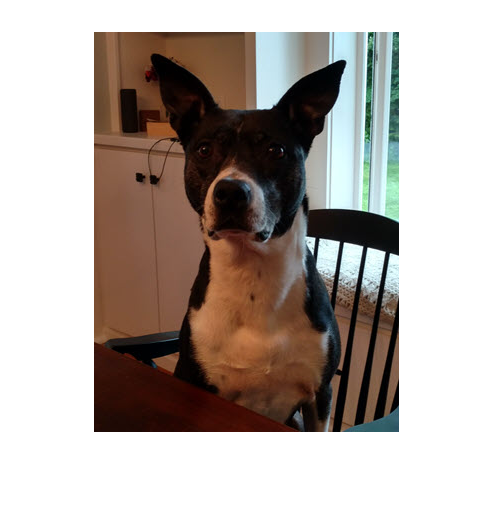

imshow(image)


% View the input size of AlexNet
size(image) % 인풋 이미지 크기

ans =    400   305     3


layer_input.InputSize % 인풋 레이어 크기

ans =    227   227     3



% Resize the image so that it can be applied to AlexNet
% 인풋 레이어 크기와 인풋 이미지의 크기가 달라서 크기를 맞춰준다
image_resized = imresize(image,[227 227]) % imresize(데이터,크기)

image_resized = 227×227×3 uint8 배열
image_resized(:,:,1) =

   110   110   112   114   116   116   114   118   129   148   151   150   146   147   148   139   133   121   108   115   124   127   126   124   121   121   120   119   117   115   112   111   110   108   108   108   111   109   107   104   102    98    91    89    86    84    82    78    73    73    72    71    70    68    69    72    76    79    79    77    75    76    76    78    78    78    76    77    80    82    83    81    80    80    81    81    81    80    80    80    81    81    82    81    81    81    81    81    81    80    79    80    81    81    82    81    80    81    81    81    82    79    78    79    79    80    80    80    80    79    79    86   118   132   130   129   128   127   126   119   163   199   200   198   196   196   196   195   195   194   194   190   190   192   191   192   191   185   181   180   178   174   167   163   161   156   153   152   151   150   148   144   140   138   135   131   13

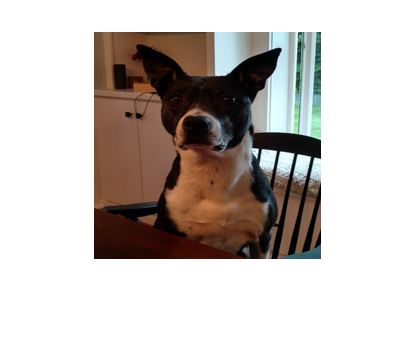

imshow(image_resized)


% Classify the image
classify(net,image_resized)

ans = categorical
     Boston bull 


[output, score] = classify(net,image_resized) %[분류결과 점수] = classify(딥러닝 모델,인풋 이미지)

output = categorical
     Boston bull 


score = 1×1000 single 행 벡터
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% Classify the image and see the score
% 각 클래스의 점수들 중 가장 높은 것이 아웃풋 클래스 점수
max(score)

ans = single
0.6152

## Image Datastore

When you import large data, you don't have to save them as variables because it costs too much time and memory. 

Instead, you can read image files by creating a datastore, which references a data source such as a folder of image files. When you create a datastore, basic information such as the file name and formats is stored.

이미지 데이터가 많을 때 변수로 일일이 저장하면 메모리와 시간소모가 크기 때문에 Image Datastore에서 이미지를 바로 이용한다.

% Create an image datastore referring to 'Lucy'
% 이미지 데이터 저장소 생성 및 저장
imageDS = imageDatastore("petImages\Lucy","IncludeSubfolders",true,"LabelSource","foldernames") % (파일경로,하위폴더 포함 옵션,라벨링 옵션)

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' ...\Choi\Desktop\세종 인공지능\인공지능 03-1주차\week3\petImages\Lucy\Lucy103.jpg';
                              ' ...\Choi\Desktop\세종 인공지능\인공지능 03-1주차\week3\petImages\Lucy\Lucy104.jpg';
                              ' ...\Choi\Desktop\세종 인공지능\인공지능 03-1주차\week3\petImages\Lucy\Lucy105.jpg'
                               ... and 29 more
                              }
                     Folders: {
                              'C:\Users\Choi\Desktop\세종 인공지능\인공지능 03-1주차\week3\petImages\Lucy'
                              }
                      Labels: [Lucy; Lucy; Lucy ... and 29 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDa

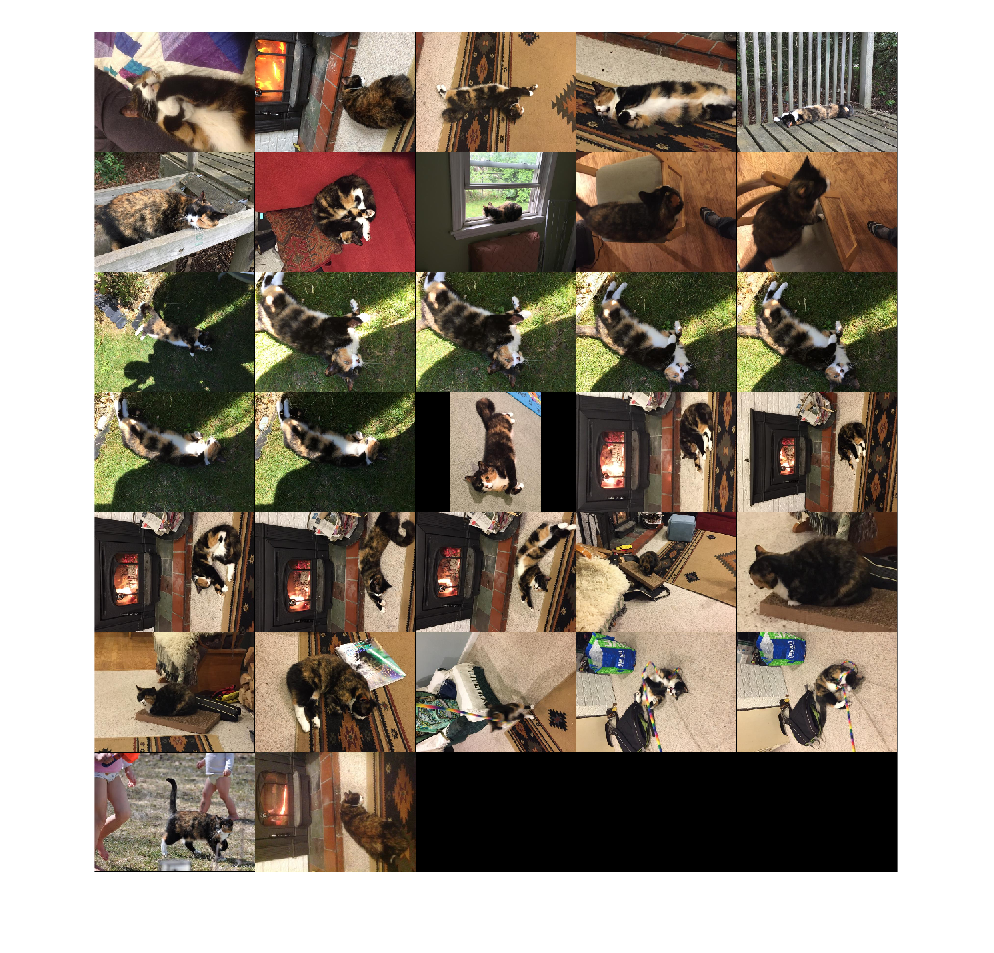


% Read and display 'Lucy' images
% 이미지데이터 저장소의 이미지 출력 
% imageAll = imtile(imageDS) % imtile() 는 전에 많이 쓰였고 무거워서 요즘엔 잘 안쓰임
% imshow(imageAll) 
montage(imageDS) % 속도가 더 빠름

For the images in an image datastore, basic preprocessing can be done by `augmentedImageDatastore` function

% 이미지 데이터 스토어의 이미지들의 여러 전처리
% 이미지 데이터 스토어의 이미지 사이즈 전처리
augImageDS = augmentedImageDatastore([227 227],imageDS)

augImageDS =   augmentedImageDatastore - 속성 있음:

             NumObservations: 32
                       Files: {32×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


% augmentedImageDatastore() : 이미지 데이터 스토어의 이미지들의 여러 전처리 기능 포함

## Modifying a Pretrained Network

An existing pretrained network does not ouput the classes you want. When performing transfer learning, you will typically change the fully connected layer and the classification layer to suit your specific application. 

% clear
% Load AlexNet and view the layers and the output classes
net = alexnet

net =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layers = net.Layers

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU             ReLU
     4   'norm1'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU             ReLU
     8   'norm2'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU             ReLU
    12   'conv4'    그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'    ReLU             ReLU
    14   'conv5'    

layer_output = layers(end) % 아웃풋 레이어

layer_output =   ClassificationOutputLayer - 속성 있음:

            Name: 'output'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   하이퍼파라미터
    LossFunction: 'crossentropyex'


layer_output.Classes % 아웃풋 레이어의 클래스, 현재 1000개의 아웃풋 클래스

ans = 1000×1 categorical 배열
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


Change the number of output classes by modifying the fully conneceted layer(23) and the classification layer(25).

% transfer learning 을 하기 위해 알렉스넷의 완전연결층의 아웃풋 클래스 개수와 아웃풋 레이어 수정
layers(23) = fullyConnectedLayer(14) % 완전연결층의 아웃풋 클래스의 개수 14로 수정

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU             ReLU
     4   'norm1'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU             ReLU
     8   'norm2'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU             ReLU
    12   'conv4'    그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'    ReLU             ReLU
    14   'conv5'    

layers(end) = classificationLayer() % 완전연결층 수정 뒤 아웃풋 레이어도 수정해줘야 오류 안남

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'    영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU             ReLU
     4   'norm1'   교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU             ReLU
     8   'norm2'   교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU             ReLU
    12   'conv4'   그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'   ReLU             ReLU
    14   'conv5'   그룹화된 컨벌루션   2 

layer_output =   ClassificationOutputLayer - 속성 있음:

            Name: ''
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   하이퍼파라미터
    LossFunction: 'crossentropyex'


ans = 'auto'

## Preparing Training Data

% Create an image datastore with the images labeled by their folder name


% Split the data into training and test data sets


% Create augmented datastores to resize the images so that they can be applied to AlexNet




## Training Options

Use Stochastic Gradient Descent with Momentum (SGDM) and decrease the initial learning rate to 0.0001.

The default initial learning rate is 0.01 but generally it should be decreased for better performances in a transfer learning.

## Training and Evaluating the Network

Train a new network. In order to use a GPU instead of a CPU, install 'Parallel Computing Toolbox' in Add-Ons explorer. A GPU is much faster than a CPU in training a neural network.

Evaluate the network by classifying the test data

    % Prediction by the new network
    % Ground truth of the test data
    % Prediction Accuracy
    % Visualization in a confusion matrix
